load('S01.mat')

ans =    2.2438e+05
   2.2712e+05
    2.291e+05
   2.3065e+05
   2.3199e+05
   2.3323e+05
   2.3448e+05
   2.3571e+05
   2.3681e+05
   2.3781e+05
   2.3875e+05
   2.3964e+05
   2.4053e+05
   2.4151e+05
   2.4254e+05
   2.4364e+05
   2.4477e+05
   2.4596e+05
   2.4719e+05
   2.4845e+05
   2.4975e+05
   2.5106e+05
   2.5236e+05
   2.5365e+05
   2.5494e+05
    2.562e+05
   2.5739e+05
   2.5853e+05
   2.5964e+05
   2.6071e+05
   2.6175e+05
    2.628e+05
   2.6386e+05
   2.6491e+05
   2.6597e+05
     2.67e+05
   2.6804e+05
   2.6909e+05
   2.7014e+05
   2.7123e+05
   2.7236e+05
   2.7348e+05
   2.7461e+05
   2.7575e+05
   2.7686e+05
   2.7794e+05
   2.7902e+05
   2.8009e+05
   2.8118e+05
   2.8227e+05
   2.8334e+05
   2.8441e+05
   2.8547e+05
   2.8653e+05
   2.8758e+05
   2.8863e+05
   2.8967e+05
   2.9071e+05
   2.9172e+05
   2.9269e+05
   2.9363e+05
   2.9452e+05
   2.9538e+05
   2.9618e+05
   2.9695e+05
   2.9772e+05
    2.985e+05
   2.9926e+05
   3.0002e+05
   3.0076e+05
   3.0148e+05



trigger=data{1,1}.trial %start and stop signal 

trigger = 12×1 uint32 column vector
    238
    360
    639
    760
   1039
   1160
   1439
   1560
   1839
   1960
   2239
   2360


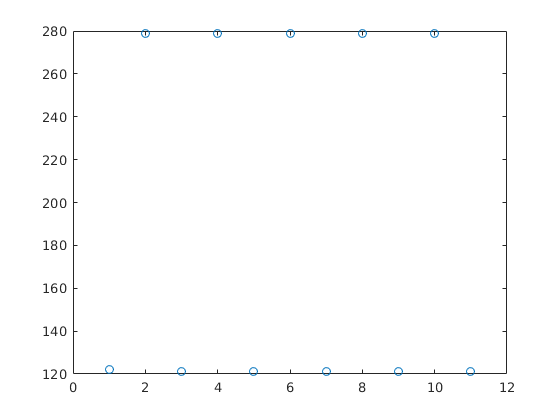

plot(diff(trigger),"o")

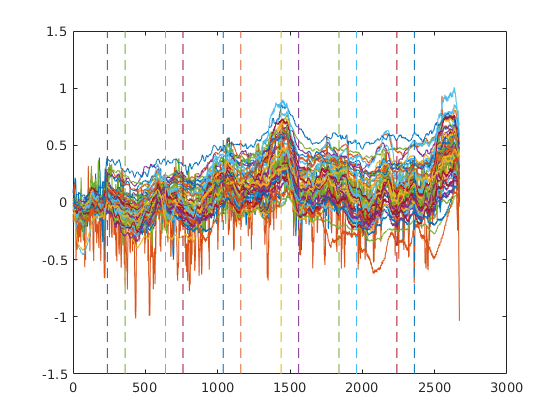

oxy=data{1,1}.X(:,1:52);
plot(oxy)
hold on
for l=trigger
    plot([l,l],[-1.5,1.5],"--")
end
hold off

Compute cusum

N=length(oxy(:,1))

N =         2671


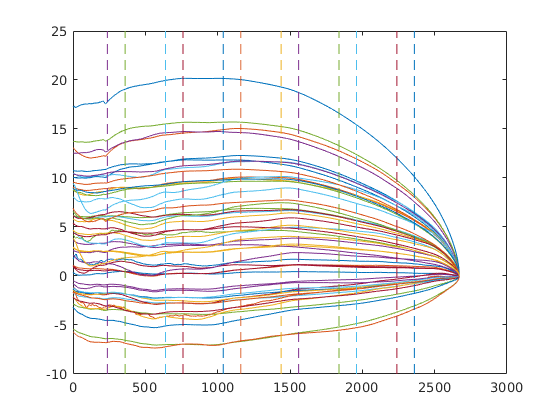

cusum_2nd=flipud(cumsum(flipud(oxy)));
t1=1:N-1;
cusum_1st=sqrt((N-1-t1)./((N-1)*t1))'.*cumsum(oxy(1:end-1,:));
t2=1:N-1;
cusum_2nd=cusum_2nd(2:end,:)*sqrt(t2/((N-t2)*N));
cusum=cusum_1st+cusum_2nd;
figure()
plot(cusum)
hold on
for l=trigger
    plot([l,l],[-10,25],"--")
end
hold off

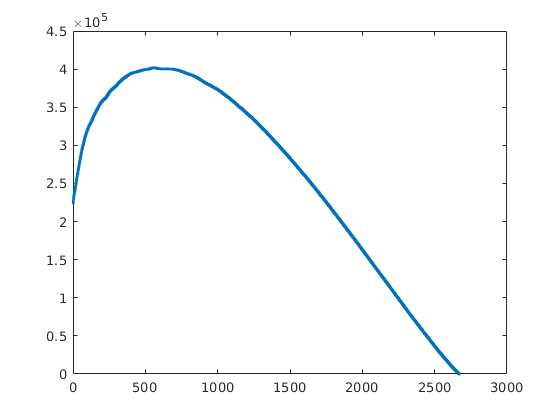

plot(diag(cusum*inv(cov(oxy(1:end-1,:)))*cusum'),".")